# Analysis of Hurricane Harvey

The Hurricane Harvey of 2017 was the deadliest hurricane in terms of damage to property. In total, it is estimated that approximately $125 Billion of damage was caused.

## Background and Scope

### Import Dataset

Storm_Events = import_county_storm_data('StormEvents_2017_finalProject.csv');

The above table contains the recorded weather events throughtout the year. Since we know that the effects of Hurricane Harvey occured between August 17th and September 3rd, We can discard the rest of the data.

h_begin = datetime('2017-08-17');
h_end   = datetime('2017-09-03');
Harvey_time_frame = Storm_Events(Storm_Events.Begin_Date_Time>h_begin & Storm_Events.End_Date_Time<h_end,:);
head(Storm_Events,5)

ans = 5×13 table
      State       Month       Event_Type         CZ_Name        Begin_Date_Time         End_Date_Time       Property_Cost    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                Event_Narrative                                                                                                                                                                                                             
    __________    _____    _________________    __________    _____________

### States

Now that our table contains only the data from the specified timeframe, we can concentrate on the states that were effected to a greater degree than the rest

states = ["Arkansas", "Kentucky", "Louisiana",... 
    "Mississippi", "North Carolina", "Tennessee", "Texas"];
states = states.upper;
states = categorical(states.upper);
% now extract the data
Harvey_data = Harvey_time_frame(Harvey_time_frame.State == states(1) | Harvey_time_frame.State == states(2) | ...
    Harvey_time_frame.State == states(3) | Harvey_time_frame.State == states(4) | Harvey_time_frame.State == states(5) & ...
    Harvey_time_frame.State == states(6) | Harvey_time_frame.State == states(7) ,:);
head(Harvey_time_frame,5)

ans = 5×13 table
    State    Month     Event_Type    CZ_Name      Begin_Date_Time         End_Date_Time       Property_Cost    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                         Event_Narrative                                                                                                                                     
    _____    ______    __________    _______    ___________________    ___________________    _____________    _________    _________    _________<

### Damage Estimate

Now that we have restricted our data to the affected states, let's find out approximately the damage done by the hurricane across these states. To acheive this, let's create a new column *Total_Cost *to calculate the total cost caused for each event. Also, at this point, let us clean the missing data for the cost of Damage to properties and the crops as we try to estimate the total damage

% Replace any missing data with 0 for the property cost
Harvey_data.Property_Cost(ismissing(Harvey_data.Property_Cost)) = 0;
% Replace any missing data with 0 for the crop cost
Harvey_data.Crop_Cost(ismissing(Harvey_data.Crop_Cost)) = 0;
Harvey_data.Total_Cost = Harvey_data.Property_Cost + Harvey_data.Crop_Cost;
groupsummary(Harvey_data,'State','sum','Total_Cost')

ans = 5×3 table
       State       GroupCount    sum_Total_Cost
    ___________    __________    ______________

    ARKANSAS           52               61000  
    KENTUCKY           20            4.35e+05  
    LOUISIANA          85          7.5277e+07  
    MISSISSIPPI        39            9.15e+05  
    TEXAS             271          7.7493e+10  


It's clear that Texas and Louisiana have taken a lot of damage from the hurricane. Let's focus on the damage on these two States.

% Create a table that contains the data for only Louisiana and Texas
TX_LS_Data = Harvey_data(Harvey_data.State == "LOUISIANA" | Harvey_data.State == 'TEXAS',:);
% removes all categories that don't occur in the Data
TX_LS_Data.State =  removecats(TX_LS_Data.State);
head(TX_LS_Data,5)

ans = 5×14 table
    State    Month       Event_Type        CZ_Name        Begin_Date_Time         End_Date_Time       Property_Cost    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                                       Event_Narrative                                                                                                                                                                                                                                                                                    

## Visualisations

Now that we have the data that we want to focus on, let's visualize the Data

First let's see what are the different types of events that have caused damage.

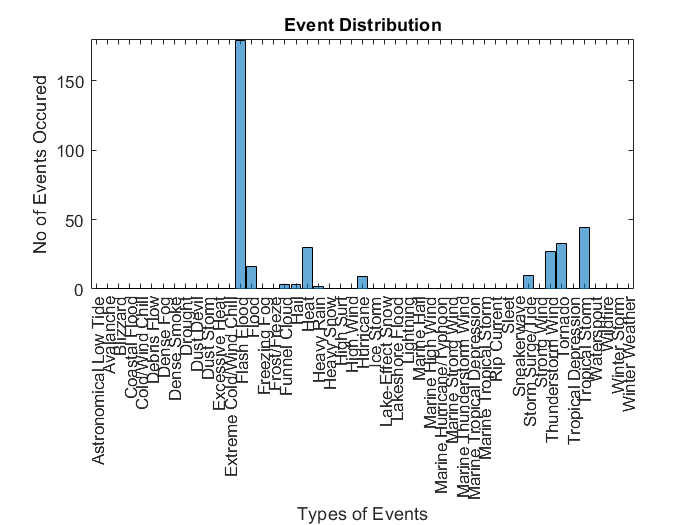

histogram(TX_LS_Data.Event_Type)
ylabel('No of Events Occured');
xlabel('Types of Events');
title("Event Distribution");

As we can see, only a few natural disasters have taken place. This is expected as we are studying Hurricane Harvey which can lead to only a few types of events. Lets see what events have occurance > 0(have occurred)

Events_occured = groupsummary(Harvey_data,'Event_Type')

Events_occured = 14×2 table
       Event_Type        GroupCount
    _________________    __________

    Flash Flood             209    
    Flood                    19    
    Funnel Cloud              3    
    Hail                     12    
    Heat                     54    
    Heavy Rain                2    
    High Wind                 1    
    Hurricane                 9    
    Lightning                 1    
    Storm Surge/Tide         10    
    Strong Wind               7    
    Thunderstorm Wind        51    
    Tornado                  45    
    Tropical Storm           44    


Let's narrow down the data to only events that occurred

% removes all categories that don't occur in the Data
TX_LS_Data.Event_Type = removecats(TX_LS_Data.Event_Type);

Let's see the Histogram again and see the distribution

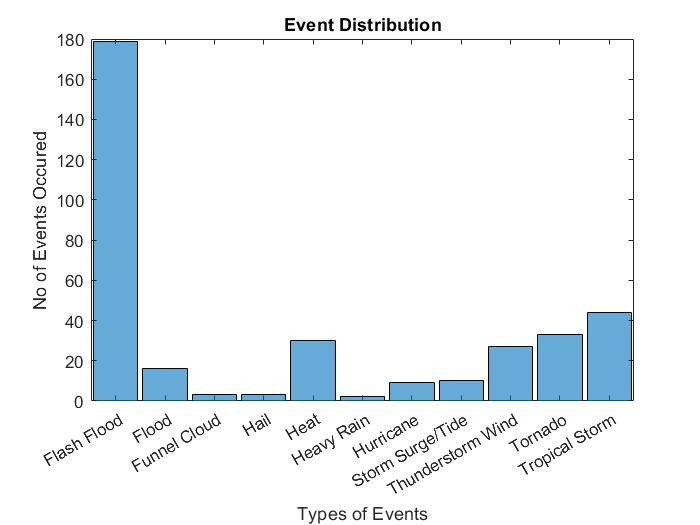

histogram(TX_LS_Data.Event_Type)
ylabel('No of Events Occured');
xlabel('Types of Events');
title("Event Distribution");

Let's also visualise the geographic distribution of the events and their impacts using a Geodensity plot or a geoscatter plot. Both of these are an excellent tool to help us visual the impact of the events that have occured

To find the this, let's divide our data by state again and use a Geobubble to visualise area of highest impacts across both States.

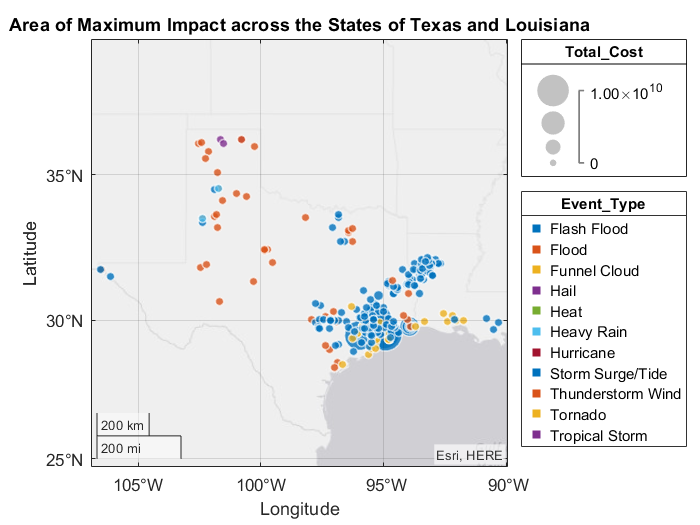

Texas = TX_LS_Data(TX_LS_Data.State == "TEXAS",:);
Louisiana = TX_LS_Data(TX_LS_Data.State == "LOUISIANA",:);
geo_bub = geobubble(TX_LS_Data,"Begin_Lat","Begin_Lon",...
    "SizeVariable","Total_Cost", "ColorVariable","Event_Type");
geo_bub.HandleVisibility ="on";
geo_bub.Title = "Area of Maximum Impact across the States of Texas and Louisiana";

Let's now observe the damage across each State.

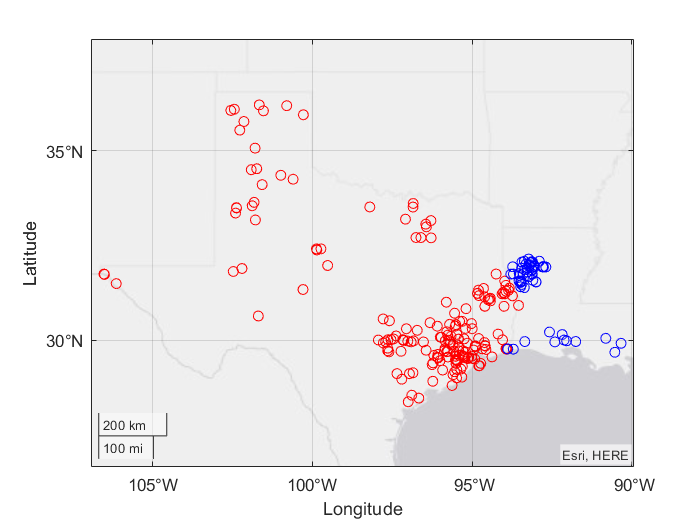

geoscatter(Texas.Begin_Lat,Texas.Begin_Lon,36,"red");
hold on
geoscatter(Louisiana.Begin_Lat,Louisiana.Begin_Lon,36,"blue");
hold off

## Analysis

From the visualisations, we see a region where there seems to be a lot of events that have taken place, let us identify the counties that have had the most number of events in the county

counties_1 = sortrows(groupsummary(Texas,'CZ_Name',"sum","Property_Cost"),"GroupCount","descend");

%rename the column names to meaningful names

counties_1.Properties.VariableNames([2 3]) = {'Number of Events', 'Total cost to Property'};
head(counties_1,3)

ans = 3×3 table
     CZ_Name     Number of Events    Total cost to Property
    _________    ________________    ______________________

    HARRIS              21                 1.0001e+10      
    GALVESTON           17                      2e+10      
    FORT BEND           13                 1.6004e+10      


counties_2 = sortrows(groupsummary(Louisiana,'CZ_Name',"sum","Property_Cost"),"GroupCount","descend");

%rename the column names to meaningful names

counties_2.Properties.VariableNames([2 3]) = {'Number of Events', 'Total cost to Property'};
head(counties_2,3)

ans = 3×3 table
      CZ_Name       Number of Events    Total cost to Property
    ____________    ________________    ______________________

    NATCHITOCHES           21                     0           
    SABINE                 15                     0           
    RED RIVER               9                     0           


We need to  identify the Counties that have had the most number of events among the states. Let us extract this information

%extracting only the first 3 entries in each table

% received the most number of events in each state.

most_affected_TX = counties_1([1,2,3],["CZ_Name","Number of Events"]);
most_affected_LS = counties_2([1,2,3],["CZ_Name","Number of Events"]);

Let's also find out the counties most affected in terms of damage to property.

counties_1 = sortrows(counties_1,"Total cost to Property","descend");
most_damaged_TX = counties_1([1 2 3],["CZ_Name","Total cost to Property"])

most_damaged_TX = 3×2 table
     CZ_Name      Total cost to Property
    __________    ______________________

    GALVESTON                2e+10      
    FORT BEND           1.6004e+10      
    MONTGOMERY             1.4e+10      


counties_2 = sortrows(counties_2,"Total cost to Property","descend");
most_damaged_LS = counties_2([1 2 3],["CZ_Name","Total cost to Property"])

most_damaged_LS = 3×2 table
     CZ_Name      Total cost to Property
    __________    ______________________

    CALCASIEU              6e+07        
    BEAUREGARD           1.5e+07        
    ACADIA                 2e+05        


## Conclusions and Recommendations

As we can see, the damage caused in Texas is very high hence it makes sense to check the counties of **Galveston, Fort Bend **immeadiately as they have experienced the heaviest brunt of the Hurricane. It also makes sense to check the other counties that have suffered as well.

We conclude our analysis here

### Thank You